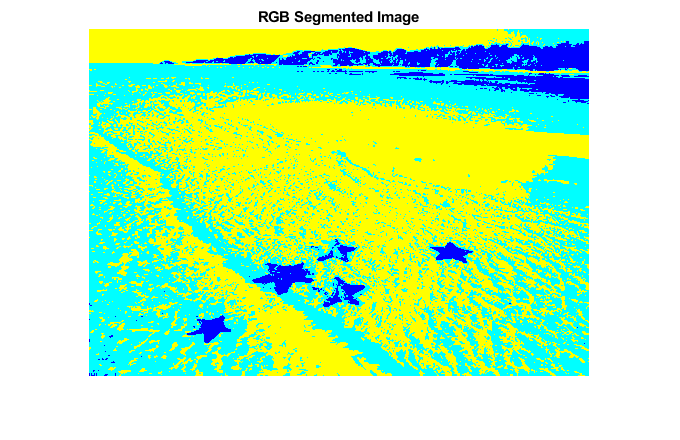

im = imread("images\starfish_5.jpg");
im = rgb2gray(im);
% 
% 
thresh = multithresh(im, 2);
seg = imquantize(im, thresh);
RGB = label2rgb(seg); 	 
figure;
imshow(RGB)
axis off
title('RGB Segmented Image')

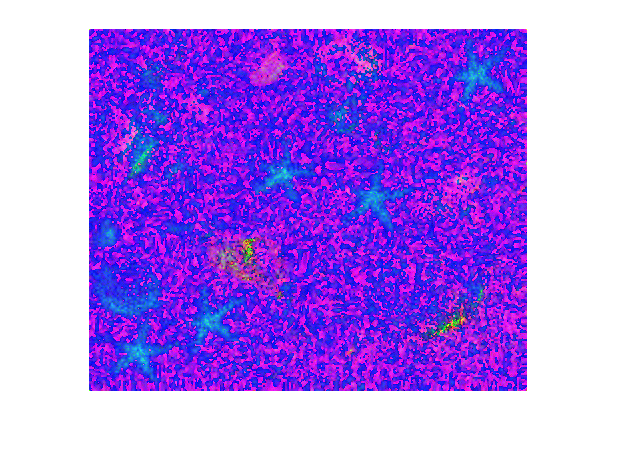

%  
% 
im = imread("images\starfish_noise2.jpg");
im = rgb2hsv(im);
imshow(im);

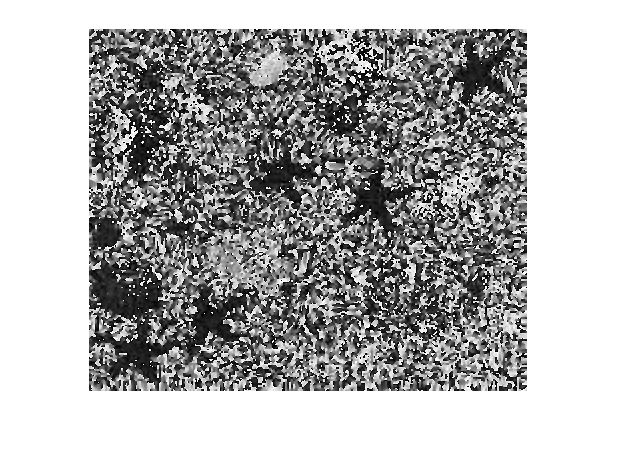


[ch1,ch2,ch3] = imsplit(im);

imshow(ch1);

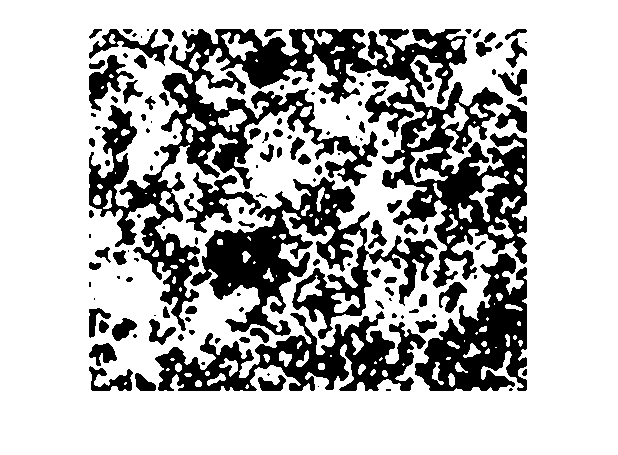

ch1 = imgaussfilt(ch1, 2);
ch1 = medfilt2(ch1, [3 3]);
ch1 = histeq(ch1);
level = graythresh(ch1);
ch1gt = imbinarize(ch1,level);
imshow(~ch1gt);

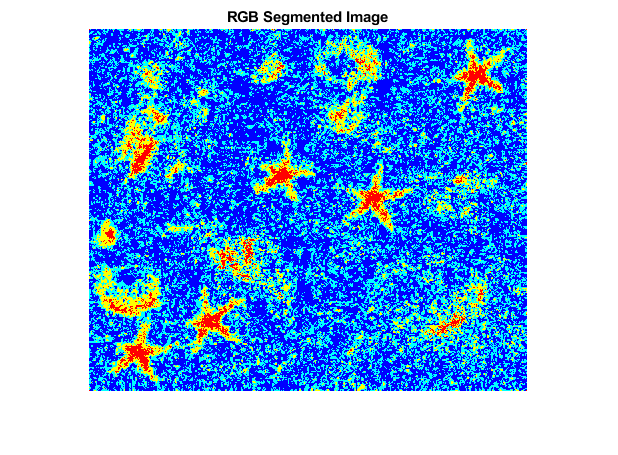


thresh = multithresh(ch2, 3);
seg = imquantize(ch2, thresh);
RGB = label2rgb(seg); 	 
figure;
imshow(RGB)
axis off
title('RGB Segmented Image')